# *DETERMINACION DEL MODELO DE REFERENCIA*

*El modelo de referencia viene dado por:*

clc
clear 
close all

Especificando el compotamiento del sistema de control en lazo cerrado

MP = 0.01;              %sobrelongacion
ts = 0.4;                 %tiempo de establecimiento

Determinando el factor de amortiguamiento y la frecencia natural

e = abs(log(MP) /sqrt(pi^2+(log(MP))^2))

e = 0.8261

wn = 4/(e*ts)

wn = 12.1053

DETERMINACION DE LA FUNCION DE TRANSFERENCIA

num = [wn^2];

den = [1 2*e*wn wn^2];

Gm = tf(num,den)

Gm =
 
        146.5
  ------------------
  s^2 + 20 s + 146.5
 
Continuous-time transfer function.



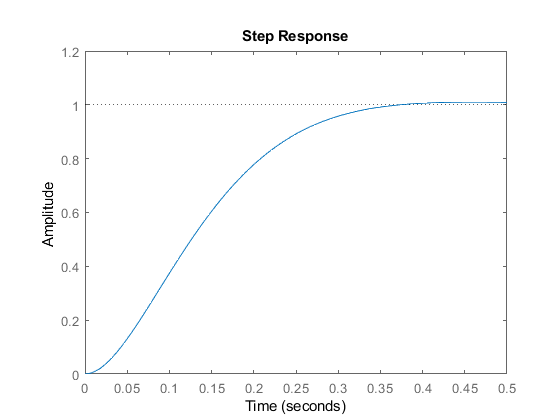

step(Gm)

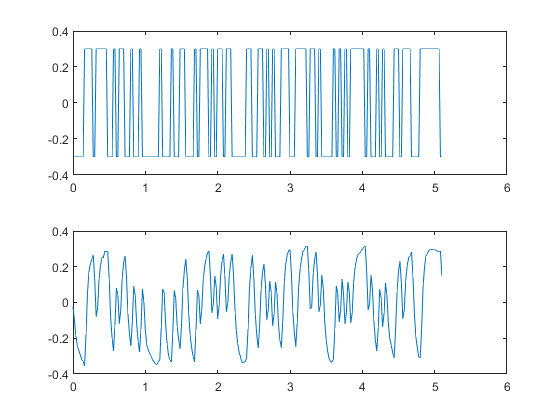


data =  [-0.0262520   -0.3000000
 -0.0988840   -0.3000000
 -0.1892160   -0.3000000
 -0.2423170   -0.3000000
 -0.2676460   -0.3000000
 -0.2938910   -0.3000000
 -0.3180000   -0.3000000
 -0.3302070   -0.3000000
 -0.3527900    0.3000000
 -0.1763990    0.3000000
  0.0512620    0.3000000
  0.1687550    0.3000000
  0.2163620    0.3000000
  0.2419970    0.3000000
  0.2658010   -0.3000000
  0.1321340   -0.3000000
 -0.0790480    0.3000000
 -0.0311350    0.3000000
  0.1315240    0.3000000
  0.2065970    0.3000000
  0.2502370    0.3000000
  0.2529840    0.3000000
  0.2847220    0.3000000
  0.2844170    0.3000000
  0.2859430   -0.3000000
  0.1361010   -0.3000000
 -0.0811840   -0.3000000
 -0.1977610   -0.3000000
 -0.2694770    0.3000000
 -0.1278760    0.3000000
  0.0796440   -0.3000000
  0.0433280   -0.3000000
 -0.1171950    0.3000000
 -0.0433420    0.3000000
  0.1348810    0.3000000
  0.2224660    0.3000000
  0.2624440   -0.3000000
  0.1376270   -0.3000000
 -0.0637890   -0.3000000
 -0.1751780   -0.3000000
 -0.2426220    0.3000000
 -0.1065130    0.3000000
  0.0912400   -0.3000000
  0.0393610   -0.3000000
 -0.1187210   -0.3000000
 -0.2151560   -0.3000000
 -0.2771070    0.3000000
 -0.1455760    0.3000000
  0.0744560   -0.3000000
  0.0045700   -0.3000000
 -0.1532050   -0.3000000
 -0.2362130   -0.3000000
 -0.2645950   -0.3000000
 -0.2844310   -0.3000000
 -0.3009100   -0.3000000
 -0.3210520   -0.3000000
 -0.3311230   -0.3000000
 -0.3448560   -0.3000000
 -0.3472970   -0.3000000
 -0.3302070   -0.3000000
 -0.3207470    0.3000000
 -0.1385570    0.3000000
  0.0765920   -0.3000000
  0.0546190   -0.3000000
 -0.1175000   -0.3000000
 -0.2282790   -0.3000000
 -0.2920600   -0.3000000
 -0.3201370   -0.3000000
 -0.3323440    0.3000000
 -0.1672430    0.3000000
  0.0671320   -0.3000000
  0.0234910   -0.3000000
 -0.1315380   -0.3000000
 -0.2044750   -0.3000000
 -0.2591010    0.3000000
 -0.1275710    0.3000000
  0.0830010    0.3000000
  0.1830980    0.3000000
  0.2426080   -0.3000000
  0.1336600   -0.3000000
 -0.0631790   -0.3000000
 -0.1840280   -0.3000000
 -0.2520820   -0.3000000
 -0.3006050   -0.3000000
 -0.3286810    0.3000000
 -0.1559520    0.3000000
  0.0665210   -0.3000000
  0.0405810   -0.3000000
 -0.1181100    0.3000000
 -0.0412060    0.3000000
  0.1251150    0.3000000
  0.2001880    0.3000000
  0.2459650    0.3000000
  0.2773980    0.3000000
  0.2880790   -0.3000000
  0.1486130   -0.3000000
 -0.0567700    0.3000000
 -0.0064160    0.3000000
  0.1483080   -0.3000000
  0.0857470   -0.3000000
 -0.0894240    0.3000000
 -0.0174020    0.3000000
  0.1446460    0.3000000
  0.2331470    0.3000000
  0.2700730   -0.3000000
  0.1458670   -0.3000000
 -0.0521920    0.3000000
 -0.0039740    0.3000000
  0.1495290    0.3000000
  0.2270440    0.3000000
  0.2728200   -0.3000000
  0.1483080   -0.3000000
 -0.0466990   -0.3000000
 -0.1712110   -0.3000000
 -0.2352980   -0.3000000
 -0.2844310   -0.3000000
 -0.3094550   -0.3000000
 -0.3378370   -0.3000000
 -0.3335640   -0.3000000
 -0.3308180   -0.3000000
 -0.3088450    0.3000000
 -0.1483230    0.3000000
  0.0805590    0.3000000
  0.1950000    0.3000000
  0.2615280   -0.3000000
  0.1391530   -0.3000000
 -0.0659250   -0.3000000
 -0.1785350   -0.3000000
 -0.2563550    0.3000000
 -0.1306220    0.3000000
  0.0726250    0.3000000
  0.1678400    0.3000000
  0.2154470   -0.3000000
  0.0994800   -0.3000000
 -0.0955270    0.3000000
 -0.0381540    0.3000000
  0.1214530   -0.3000000
  0.0549240   -0.3000000
 -0.1300120    0.3000000
 -0.0643990    0.3000000
  0.1126030   -0.3000000
  0.0543140   -0.3000000
 -0.1184150   -0.3000000
 -0.2090530   -0.3000000
 -0.2508620    0.3000000
 -0.1074290    0.3000000
  0.1074150    0.3000000
  0.2108690    0.3000000
  0.2639700    0.3000000
  0.2892990    0.3000000
  0.2960130   -0.3000000
  0.1602100   -0.3000000
 -0.0573800   -0.3000000
 -0.1678540   -0.3000000
 -0.2450630    0.3000000
 -0.1123120    0.3000000
  0.0894090    0.3000000
  0.1898120    0.3000000
  0.2465750    0.3000000
  0.2874680    0.3000000
  0.2984550    0.3000000
  0.3140190    0.3000000
  0.3152390   -0.3000000
  0.1776050   -0.3000000
 -0.0369330    0.3000000
 -0.0250320    0.3000000
  0.1596000    0.3000000
  0.2380300    0.3000000
  0.2844170   -0.3000000
  0.1534960   -0.3000000
 -0.0500560    0.3000000
 -0.0109930    0.3000000
  0.1522760   -0.3000000
  0.0787280   -0.3000000
 -0.1013260   -0.3000000
 -0.2102730   -0.3000000
 -0.2703930   -0.3000000
 -0.3140330   -0.3000000
 -0.3292920   -0.3000000
 -0.3338690   -0.3000000
 -0.3158640    0.3000000
 -0.1431350    0.3000000
  0.0921560   -0.3000000
  0.0506520   -0.3000000
 -0.1083450    0.3000000
 -0.0451730    0.3000000
  0.1306080   -0.3000000
  0.0448540   -0.3000000
 -0.1202460    0.3000000
 -0.0549390    0.3000000
  0.1165700   -0.3000000
  0.0573660   -0.3000000
 -0.1150580    0.3000000
 -0.0555490    0.3000000
  0.1141290    0.3000000
  0.2004930    0.3000000
  0.2410820    0.3000000
  0.2706840    0.3000000
  0.2722100    0.3000000
  0.2902150    0.3000000
  0.2972340    0.3000000
  0.3112720    0.3000000
  0.3164600   -0.3000000
  0.1745530   -0.3000000
 -0.0421210    0.3000000
 -0.0082470    0.3000000
  0.1519700   -0.3000000
  0.0756760   -0.3000000
 -0.1043770   -0.3000000
 -0.2114940   -0.3000000
 -0.2728340    0.3000000
 -0.1425240    0.3000000
  0.0720140   -0.3000000
  0.0271530   -0.3000000
 -0.1361160    0.3000000
 -0.0613470    0.3000000
  0.1064990   -0.3000000
  0.0427170   -0.3000000
 -0.1196360   -0.3000000
 -0.2020340   -0.3000000
 -0.2410960   -0.3000000
 -0.2795480   -0.3000000
 -0.3088450    0.3000000
 -0.1513740    0.3000000
  0.0598070    0.3000000
  0.1757740    0.3000000
  0.2291800   -0.3000000
  0.1055840   -0.3000000
 -0.0912550    0.3000000
 -0.0390700    0.3000000
  0.1251150    0.3000000
  0.2069020    0.3000000
  0.2496270    0.3000000
  0.2630540    0.3000000
  0.2807550   -0.3000000
  0.1446460   -0.3000000
 -0.0613470   -0.3000000
 -0.1913520   -0.3000000
 -0.2536080   -0.3000000
 -0.3039620   -0.3000000
 -0.3082350    0.3000000
 -0.1452710    0.3000000
  0.0912400    0.3000000
  0.1986620    0.3000000
  0.2609180    0.3000000
  0.2749560    0.3000000
  0.2908250    0.3000000
  0.2947930    0.3000000
  0.2960130    0.3000000
  0.2938770    0.3000000
  0.2941820    0.3000000
  0.2935720    0.3000000
  0.2838060    0.3000000
  0.2874680    0.3000000
  0.2862480   -0.3000000
  0.1489190   -0.3000000];
Ts = 20e-3;
t = 0:Ts:(256-1)*Ts;
figure("Name",'Motor DC')
subplot(2,1,1)
plot(t',data(:,2))
subplot(2,1,2)
plot(t',data(:,1))